close all; clear; clc;

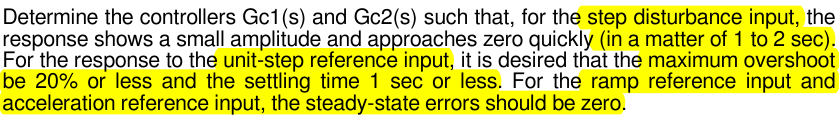

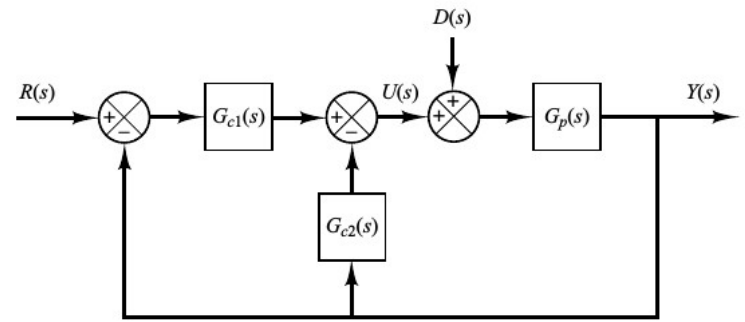

## Función de transferencia de la planta

syms s
K  = 2;
A  = [1 1];
B  = conv([1 0],conv([1 3],[1 5]));
Gp = tf(K*A,B)

Gp =
 
       2 s + 2
  ------------------
  s^3 + 8 s^2 + 15 s
 
Continuous-time transfer function.



Gp_sym = poly2sym(K*A, s)/poly2sym(B, s)

$$Gp\_sym = \frac{2\,s+2}{s^{3}+8\,s^{2}+15\,s}$$

## Polos/ceros de la planta

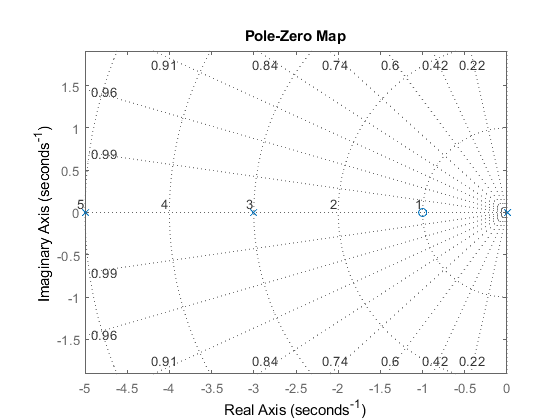

pzmap(Gp); grid on; axis('equal')

Bien, hay que notar que el sistema a lazo abierto tiene un polo en el origen, por lo tanto tiene un integrador puro a la salida.

Por ejemplo podría ser debido a que es una salida de posición obtenida por integración de la velocidad.

# Análisis de las funciones de transferencia

## Función de transferencia del controlador auxiliar

syms kp kd ki tau_z
Gc_sym = collect((kp + ki/s + kd*s)/poly2sym(A, s)) % Con el filtro de los ceros como la teoría

$$Gc\_sym = \frac{\mathrm{kd}\,s^{2}+\mathrm{kp}\,s+\mathrm{ki}}{s^{2}+s}$$

## Función de transferencia a lazo cerrado desde la perturbación

Gd_sym = collect(Gp_sym/(1 + Gp_sym*Gc_sym), s)

$$Gd\_sym = \frac{2\,s^{2}+2\,s}{s^{4}+8\,s^{3}+\left(2\,\mathrm{kd}+15\right)\,s^{2}+\left(2\,\mathrm{kp}\right)\,s+2\,\mathrm{ki}}$$

## Función de transferencia a lazo cerrado desde la referencia

syms Gc1_sym
Gr_sym = collect(Gc1_sym*Gp_sym/(1 + Gp_sym*Gc_sym), s)

$$Gr\_sym = \frac{\left(2\,{\mathrm{Gc}}_{1,\mathrm{sym}}\right)\,s^{2}+\left(2\,{\mathrm{Gc}}_{1,\mathrm{sym}}\right)\,s}{s^{4}+8\,s^{3}+\left(2\,\mathrm{kd}+15\right)\,s^{2}+\left(2\,\mathrm{kp}\right)\,s+2\,\mathrm{ki}}$$

## Función de transferencia de C1

[num, den] = numden(Gr_sym);
w          = coeffs(den, s, 'All');
w          = sum(w(end-2:end).*s.^[2 1 0]);
num        = simplify(num/Gc1_sym);
Gc1_sym    = w/num

$$Gc1\_sym = \frac{\left(2\,\mathrm{kd}+15\right)\,s^{2}+2\,\mathrm{kp}\,s+2\,\mathrm{ki}}{2\,s\,\left(s+1\right)}$$

## Función de transferencia de C2

Gc2_sym = collect(Gc_sym - Gc1_sym, s)

$$Gc2\_sym = \frac{-15\,s}{2\,s+2}$$

## Función de transferencia a LC respecto a la ref. final

Gr_sym = collect(subs(Gr_sym), s)

$$Gr\_sym = \frac{\left(2\,\mathrm{kd}+15\right)\,s^{2}+\left(2\,\mathrm{kp}\right)\,s+2\,\mathrm{ki}}{s^{4}+8\,s^{3}+\left(2\,\mathrm{kd}+15\right)\,s^{2}+\left(2\,\mathrm{kp}\right)\,s+2\,\mathrm{ki}}$$

# Asignación de polos

## Polinomio característico a LC

[num, den]  = numden(Gr_sym);
numGr       = collect(num, s)

$$numGr = \left(2\,\mathrm{kd}+15\right)\,s^{2}+\left(2\,\mathrm{kp}\right)\,s+2\,\mathrm{ki}$$

denGr       = collect(den, s)

$$denGr = s^{4}+8\,s^{3}+\left(2\,\mathrm{kd}+15\right)\,s^{2}+\left(2\,\mathrm{kp}\right)\,s+2\,\mathrm{ki}$$

## Polinomio objetivo a LC

syms w1 w2 z1 z2
obj_sym = collect((s^2 + 2*z1*w1*s + w1^2)*(s^2 + 2*z2*w2*s + w2^2), s);
disp('OBJETIVO');

OBJETIVO


disp(obj_sym);

$$s^{4}+\left(2\,w_{1}\,z_{1}+2\,w_{2}\,z_{2}\right)\,s^{3}+\left({w_{1}}^{2}+4\,z_{1}\,z_{2}\,w_{1}\,w_{2}+{w_{2}}^{2}\right)\,s^{2}+\left(2\,z_{2}\,{w_{1}}^{2}\,w_{2}+2\,z_{1}\,w_{1}\,{w_{2}}^{2}\right)\,s+{w_{1}}^{2}\,{w_{2}}^{2}$$

clear i
syms wn phi
assume(wn, 'real')
assume(phi, 'real')
assumeAlso(wn > 0);  % Restricción razonable para frecuencia natural

% Definir el número complejo s = wn * exp(1j*phi)
s_eval  = wn * (cos(phi) + i*sin(phi));

% Polinomio
pol     = s^4 + 8*s^3;

% Evaluar el polinomio en s = wn*e^{j phi}
pol_eval = subs(pol, s, s_eval);
mag_expr = simplify(expand(pol_eval*pol_eval'))

$$mag\_expr = {\mathrm{wn}}^{6}\,\left({\mathrm{wn}}^{2}+16\,\cos\left(\varphi \right)\,\mathrm{wn}+64\right)$$

grad_phi = simplify(diff(mag_expr, phi))

$$grad\_phi = -16\,{\mathrm{wn}}^{7}\,\sin\left(\varphi \right)$$

mag_expr = subs(mag_expr, phi, pi)

$$mag\_expr = {\mathrm{wn}}^{6}\,\left({\mathrm{wn}}^{2}-16\,\mathrm{wn}+64\right)$$

mag_expr = simplify(sqrt(simplify(mag_expr)))

$$mag\_expr = {\mathrm{wn}}^{3}\,\left|\mathrm{wn}-8\right|$$

Basicamente es lo mismo para otros valores de $\phi$ que no sean $\pi$.

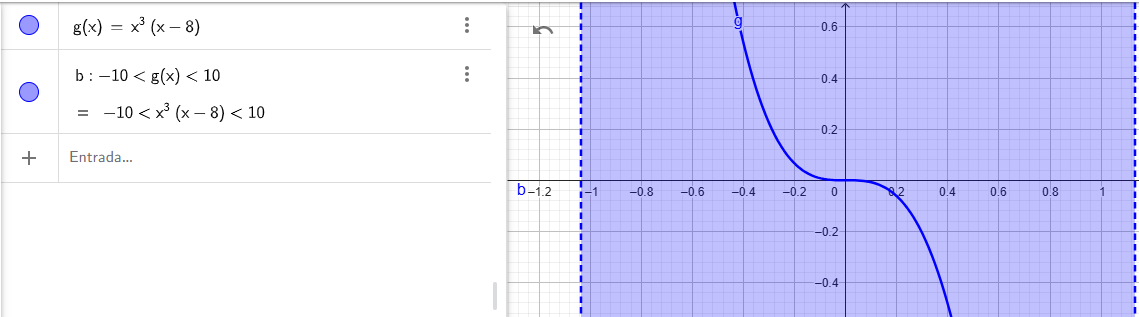

syms wn zeta
coeffnum     = coeffs(numGr, 's', 'All');
coeffnum     = coeffnum/coeffnum(1);
coeffobj     = [1 2*zeta*wn wn^2];
eq           = coeffnum(2:end)==coeffobj(2:end);
sol_zeros    = solve(eq, [kp, kd, ki], 'ReturnConditions',true);

kp_eq        = sol_zeros.kp(1)

$$kp\_eq = \frac{2\,z\,\zeta }{\mathrm{wn}}$$

kd_eq        = sol_zeros.kd(1)

$$kd\_eq = \frac{2\,z-15\,{\mathrm{wn}}^{2}}{2\,{\mathrm{wn}}^{2}}$$

ki_eq        = sol_zeros.ki(1)

$$ki\_eq = z$$

aux          = subs(denGr, [kp, kd, ki], [kp_eq, kd_eq, ki_eq]);
coefs_poly   = coeffs(aux, 's', 'All')

$$coefs\_poly = \left(\begin{array}{ccccc} 1 & 8 & \frac{2\,z-15\,{\mathrm{wn}}^{2}}{{\mathrm{wn}}^{2}}+15 & \frac{4\,z\,\zeta }{\mathrm{wn}} & 2\,z \end{array}\right)$$

[nums, dens] = numden(Gr_sym);
collect(nums, s)

$$ans = \left(2\,\mathrm{kd}+15\right)\,s^{2}+\left(2\,\mathrm{kp}\right)\,s+2\,\mathrm{ki}$$

collect(dens, s)

$$ans = s^{4}+8\,s^{3}+\left(2\,\mathrm{kd}+15\right)\,s^{2}+\left(2\,\mathrm{kp}\right)\,s+2\,\mathrm{ki}$$

% Supongamos que ya tenés definido:
% zeta_min, zeta_max, wn_min, wn_max, z_min, z_max
% z_norm, wn_norm, zeta_norm : punto actual (normalizado)
% Radio_norm : radio de búsqueda en coordenadas normalizadas
% T : temperatura actual
% costo_actual : costo en el punto actual

zeta_min = 0.3; zeta_max  = 1.2; zeta_range = zeta_max-zeta_min;
wn_min   = 0.30 ;wn_max   = 0.75; wn_range  = wn_max -wn_min;
z_min    = 2;   z_max     = 50;  z_range    = z_max- z_min;

% Coordenadas del punto actual (normalizadas)
coord_norm = zeros(1,3);
while true
    coord_norm = rand(1,3);  % vector aleatorio entre -1 y 1
    if norm(coord_norm) <= 1
        break
    end
end

T               = 15000;
alpha_T         = 0.988;
alpha_R         = 1;
L_max           = 100;
T_min           = 0.001;
Radio_norm      = 1;
costo_actual    = inf;
n               = 1;
costos          = 0;
L               = L_max;

while T > T_min
    if (costo_actual < 2)
        L = L_max/5;
    end
    for i = 1:L
        % ======== Generar vecino dentro de una esfera de Radio_norm ============
        % Generar vector aleatorio de dirección y escalarlo a Radio_norm
        while true
            delta = 2*rand(1,3) - 1;  % vector aleatorio entre -1 y 1
            if norm(delta) <= 1
                break
            end
        end
        delta       = delta / norm(delta);            % dirección normalizada
        magnitud    = rand() * Radio_norm;            % magnitud aleatoria hasta el radio
        vecino_norm = coord_norm + magnitud * delta;  % nuevo punto normalizado
        
        % Limitar coordenadas normalizadas al rango [0, 1]
        vecino_norm = min(max(vecino_norm, 0), 1);
        
        % ======== Convertir a coordenadas reales ================================
        z     = vecino_norm(1)*z_range     + z_min;
        wn    = vecino_norm(2)*wn_range    + wn_min;
        zeta  = vecino_norm(3)*zeta_range  + zeta_min;
        
        % ======== Calcular ganancias del controlador ============================
        kp_val = 2*zeta*z/wn;
        kd_val = (2*z - 15*wn^2)/(2*wn^2);
        ki_val = z;
        
        % ======== Función de transferencia y costo =============================
        num = [(2*kd_val + 15) 2*kp_val 2*ki_val];
        den = [1  8  (2*kd_val + 15)  2*kp_val  2*ki_val];
        G   = tf(num, den);
        
        % Evitar errores en sistemas inestables
        try
            aux         = stepinfo(G);
            costo_nuevo = ((aux.Overshoot - 20)/20 + (aux.SettlingTime - 1)); % costo nuevo
        catch
            costo_nuevo = inf;
        end
        
        % ======== Criterio de aceptación de recocido simulado ==================
        deltaE = costo_nuevo - costo_actual;
        
        if deltaE < 0
            aceptar = true;  % Mejor solución
        else
            aceptar = rand() < exp(-deltaE / T);  % Probabilidad de aceptación
        end
        
        % ======== Actualización si se acepta ===================================
        if aceptar
            z_norm       = vecino_norm(1);
            wn_norm      = vecino_norm(2);
            zeta_norm    = vecino_norm(3);
            costo_actual = costo_nuevo;
            coord_norm   = vecino_norm;
        end
    end
    costos(n)   = costo_actual;
    n           = n + 1;
    T           = alpha_T*T;
    Radio_norm  = Radio_norm*alpha_R;
end

costo_actual

costo_actual = 0.6381

Radio_norm

Radio_norm = 1

aux.Overshoot

ans = 38.7511

aux.SettlingTime

ans = 1.3690

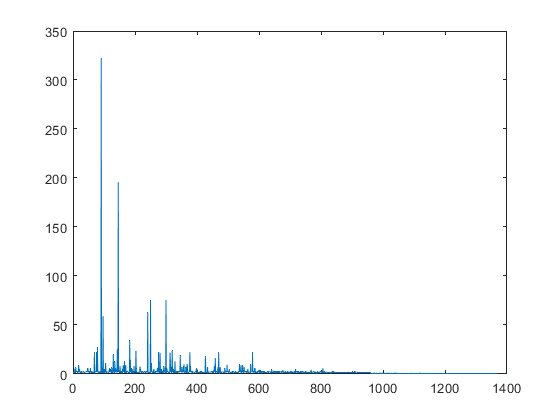

plot(costos)

Practicamente no cambia cambiando Zeta. Aunque sí, para valores bajos cerca de 0.4 no anda muy bien. De 0.4 a 1.1 en principio

Cambia con wn. Cuando le vas poniendo valores mas grandes de wn se separan mas los polos de los ceros y además los otros dos polos se hacer reales y distintos. Por eso mas o menos desde 0.45 a 0.68 o 0.7

Variando el Z cambia la frecuencia natural amortiguada casi solamente. Tendría sentido valores de 5 a 30 mas o menos.

z_vec       = linspace(5, 30, 20);
%z_vec        = [5];
wn_vec      = linspace(0.40, 0.70, 20);
%wn_vec       = [0.70];
zeta_vec     = linspace(0.4, 1.1, 10);
%zeta_vec    = 0.85;  

n           = 1;
indices     = zeros(1, 2);
polos       = zeros(1, 4);
ganancias   = zeros(1, 3);

for i = 1:length(wn_vec)
    wn = wn_vec(i);
    for j = 1:length(z_vec)
        z       = z_vec(j);
        for k = 1:length(zeta_vec)
            zeta = zeta_vec(k);
            coefs   = double(subs(coefs_poly));
            rai     = roots(coefs);
            if (all(real(rai) < 0))
                gains             = [double(subs(kp_eq)), double(subs(kd_eq)), double(subs(ki_eq))];
                num               = sym2poly(subs(nums, [kp, kd, ki], gains));
                den               = sym2poly(subs(dens, [kp, kd, ki], gains));
                G                 = tf(num, den);
                aux               = stepinfo(G);
                indices(n, 1:2)     = [i, j];
                polos(n, 1:4)       = rai.';
                ganancias(n, 1:end) = gains;
                n                   = n + 1;
                if ((aux.Overshoot < 30) && (aux.SettlingTime < 2))
                    disp('Si')
                end
            end
        end
    end
end

size(polos)

ans =         4000           4


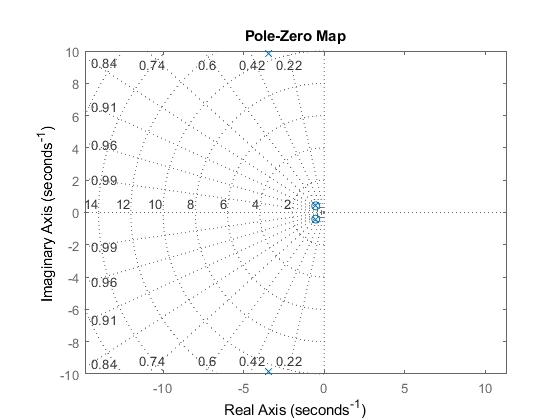

n =3566;
num               = sym2poly(subs(nums, [kp, kd, ki], ganancias(n,:)));
den               = sym2poly(subs(dens, [kp, kd, ki], ganancias(n,:)));
G                 = tf(num, den);
pzmap(G); grid on; axis('equal')

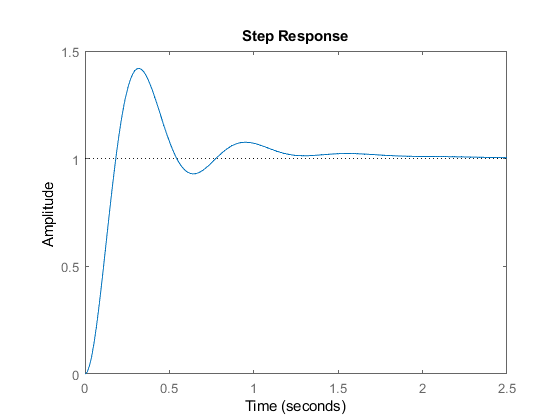

step(G)

stepinfo(G)

ans = struct with fields:
        RiseTime: 0.1230
    SettlingTime: 1.6861
     SettlingMin: 0.9292
     SettlingMax: 1.4197
       Overshoot: 41.9723
      Undershoot: 0
            Peak: 1.4197
        PeakTime: 0.3205
